load('Data\Calibrated_Airfoil_Pressure_Pa_Interpolated_Coeffs.mat')
load('Data\calibrated_manometer_data_Pa.mat')
load('Code\location.mat')
velocity = importdata('Data/velocities_manometer.csv')

velocity =    35.5008   34.8833   36.1844   35.5981   36.2791   36.1813   35.8883   36.0871   36.8536   36.5693   35.7921


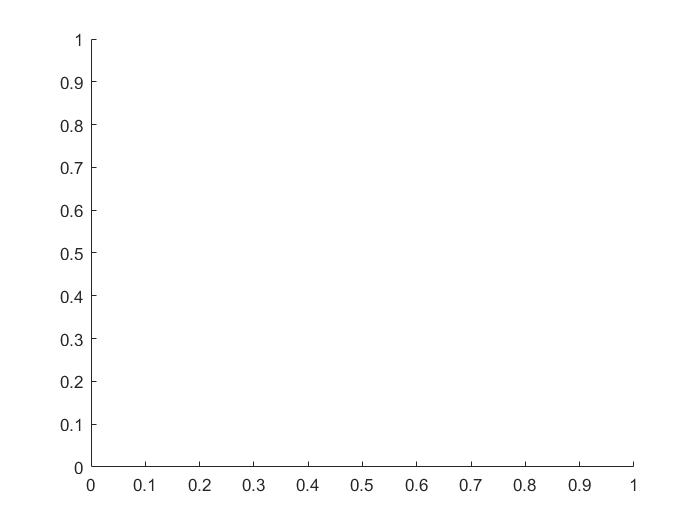

h = figure;
axis tight manual; 

gif = 'Animated.gif';
q = 1/2 * 1.225 * velocity.^2;

p = [p0; p3; p6; p8; 
     p10; p11; p13; p15;
     p16; p17; p20];
idx = [0, 3, 6, 8, 10, 11, 13, 15, 16, 17, 20];
formatspec = 'XFOIL Analysis/clark_y_%d.cp';

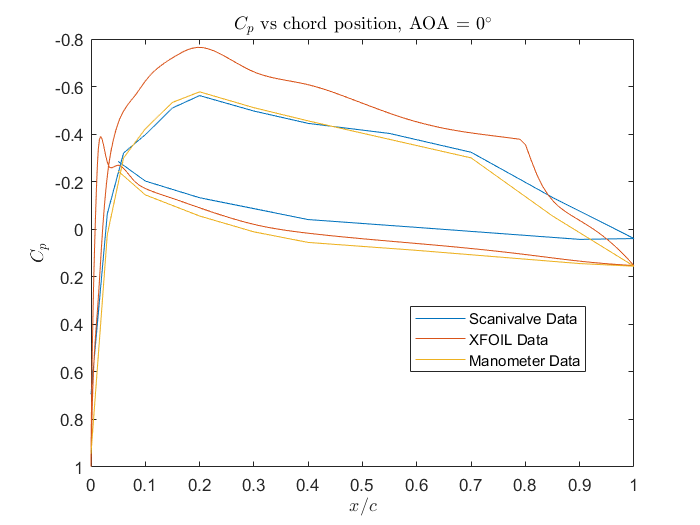

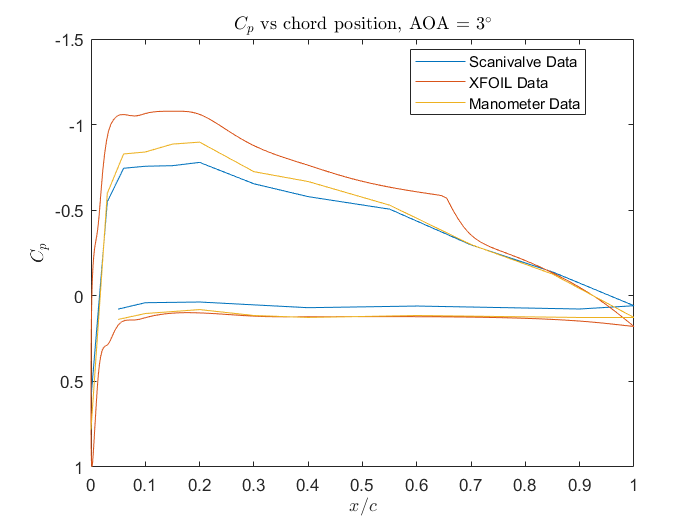

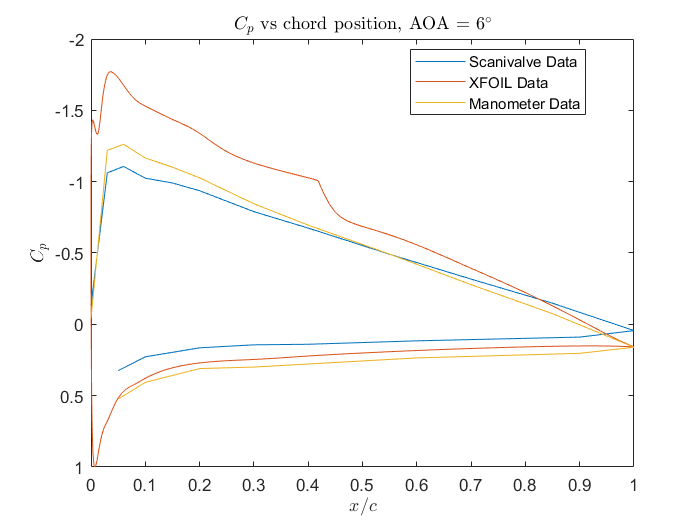

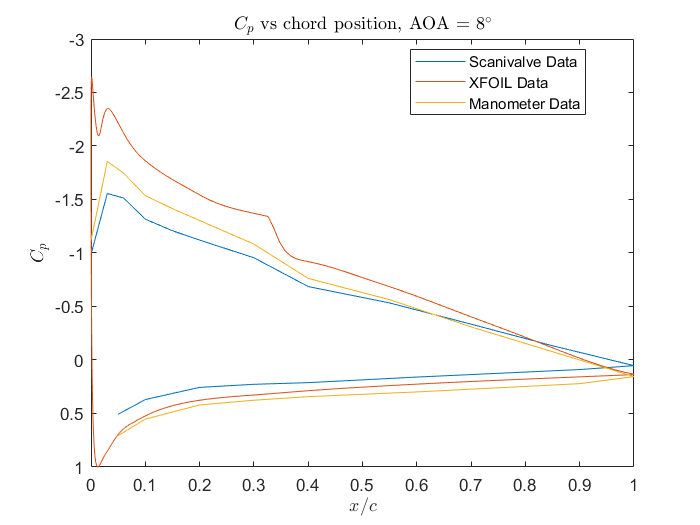

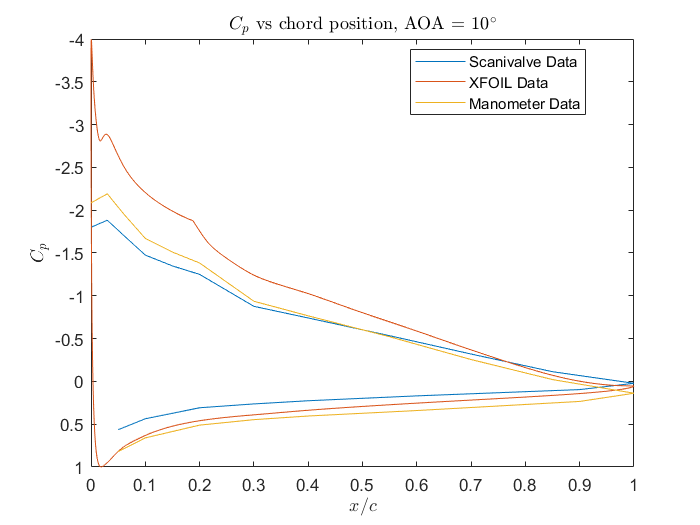

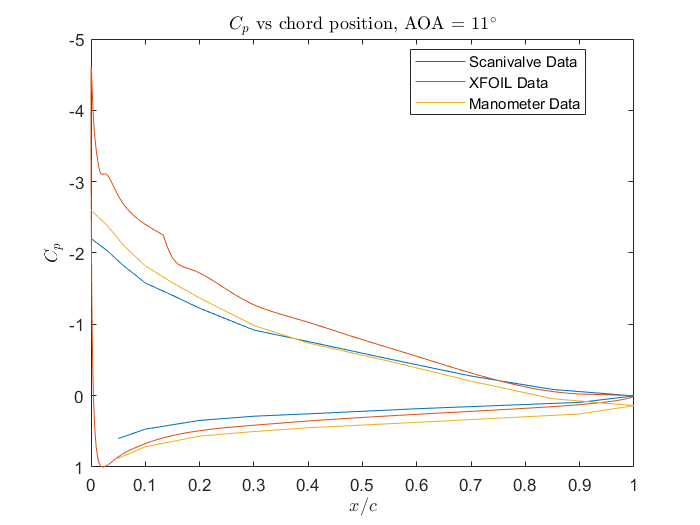

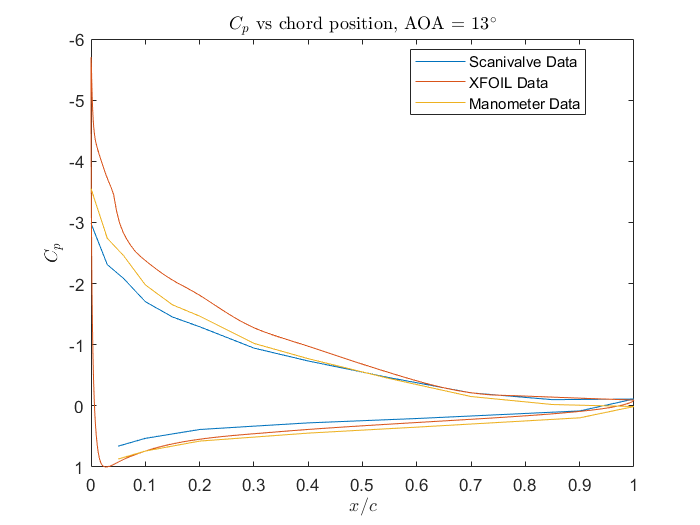

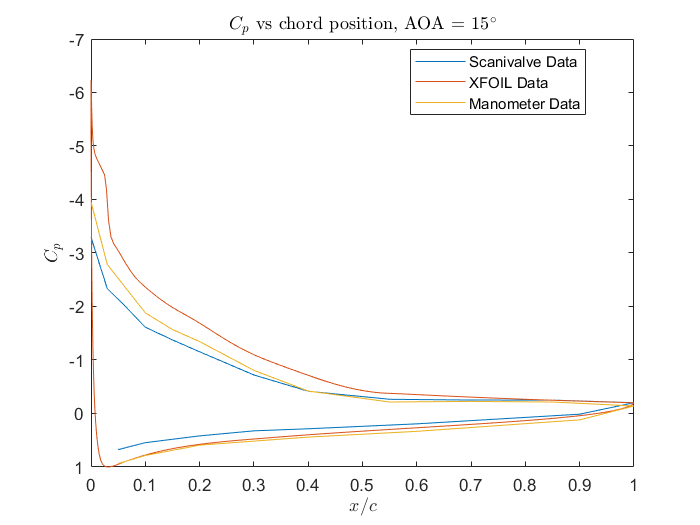

for i = 1:11
    
    figure
    plot(location, p(i, :)/q(1,i));
    filename = sprintf(formatspec, idx(1,i));
    A = importdata(filename,' ', 3);
    hold on
    plot(A.data(:,1), A.data(:, 3))
    plot(location, airfoil_manometer(i, :)/q(1,i))
    hold off
    set(gca, 'YDir','reverse')
    xlim([0 1])
    xlabel('$x/c$', "interpreter", "latex")
    ylabel('$C_p$',"interpreter",'latex')
    title(strcat(sprintf('$C_p$ vs chord position, AOA = %d', idx(1, i)), '$^\circ$'), 'interpreter', 'latex')
    legend('Scanivalve Data', 'XFOIL Data','Manometer Data','location',"best")
    
    frame = getframe(h); 
    im = frame2im(frame); 
    [imind,cm] = rgb2ind(im,256);
    
    if i == 1
        imwrite(imind,cm,gif,'gif', 'Loopcount',inf);  
    else 
        imwrite(imind,cm,gif,'gif','WriteMode','append'); 
    end
    
end